clear 
aircraftname="B";
if aircraftname ~= "Other"
    AircraftData
else
    %AircraftDataEntry
    Aircraft.Pax = 150;
    Aircraft.Bags = Aircraft.Pax;
        Aircraft.Cargo = 0;
        Aircraft.MaxPyld = 27500;
        Aircraft.Range = 5500;
        Aircraft.CruiseMach = 0.85;
        Aircraft.Engines = 2;
        Aircraft.PaxWeight = 110;
        Aircraft.BagWeight = 0 ;
        Aircraft.AR = 20;
        Aircraft.e = 0.8;
        Aircraft.CD0 = 0.015;
        Aircraft.c_TO = 0.3;
        Aircraft.c_cruise = 0.525;
        Aircraft.c_climb = Aircraft.c_cruise;
        Aircraft.c_approach = Aircraft.c_cruise;
        Aircraft.CL_TO = 2  ;
        Aircraft.CL_Ld = 2.1;
        Aircraft.groundRollFraciton = 0.6;
        Aircraft.OEIPenalty = 0.5;
        Aircraft.ClimbDescentCredit = 200; %200 nautical miles
        Aircraft.We_A = 0.97;
        Aircraft.We_exp = -0.06;
        Aircraft.CruiseAlt = 36000;
        Aircraft.reserveRatio = 1.05;
end
struct2table(Aircraft)

ans = 1×28 table
    Pax    Bags    Cargo    MaxPyld    Range    CruiseMach    Engines    PaxWeight    BagWeight    AR      e       CD0     c_TO    c_cruise    c_climb    c_approach    CL_TO    CL_Ld    groundRollFraciton    OEIPenalty    ClimbDescentCredit    We_A    We_exp    CruiseAlt    reserveRatio     TW     WS     Constraints
    ___    ____    _____    _______    _____    __________    _______ 

disp(strcat("Aircraft Name: ",aircraftname));

Aircraft Name: B


MissionSpec;
LoadMissionDefaults;

 
[MissionTable,Aircraft] = mission(missionDef,Aircraft,MissionDefaults);
[MTOW,Aircraft]=MTOWSolver(MissionTable,Aircraft);
Aircraft.MTOW=MTOW;
Range = pyldRangeEstimator(Aircraft,MissionTable);
Aircraft.RangemaxPyld = Range;

FerryRange=pyldRangeEstimator(Aircraft, MissionTable,0);
Aircraft.FerryRange = FerryRange;
MissionTbl=table(MissionTable.WeightFractions(:,1), MissionTable.WeightFractions(:,2), MissionTable.WeightFractions(:,3), 'VariableNames', ["Segment Fraction", "Mission Fraction", "Segment Type"]);
WeightTbl =table([Aircraft.MTOW; Aircraft.EmptyWeight; Aircraft.DesignPayload; Aircraft.MaxPyld; Aircraft.DesignFuel],'RowNames',["Max Takeoff Weight", "Empty Weight", "Design Payload", "Maximum Payload", "Aircraft Design Fuel"],'VariableNames',"Weights (kg)");
MissionTbl, WeightTbl

MissionTbl = 12×3 table
    Segment Fraction    Mission Fraction    Segment Type
    ________________    ________________    ____________

       {[0.9950]}          {[0.9950]}         {'WARM'}  
       {[0.9900]}          {[0.9850]}         {'TKOF'}  
       {[0.9800]}          {[0.9653]}         {'CLMB'}  
       {[0.6537]}          {[0.6310]}         {'CRUS'}  
       {[0.9950]}          {[0.6279]}         {'DSCT'}  
       {[0.9950]}          {[0.6248]}         {'LNDG'}  
       {[0.9883]}          {[0.6174]}         {'HOLD'}  
       {[0.9990]}          {[0.6168]}         {'TAXI'}  
       {[0.9900]}          {[0.6106]}         {'ALCL'}  
       {[0.9944]}          {[0.6072]}         {'ALCR'}  
       {[0.9950]}          {[0.6042]}         {'ALLD'}  
       {[0.9524]}          {[0.5754]}         {'RSRV'}  


WeightTbl = 5×1 table
                            Weights (kg)
                            ____________

    Max Takeoff Weight        2.8e+05   
    Empty Weight              1.3e+05   
    Design Payload              33000   
    Maximum Payload             75000   
    Aircraft Design Fuel      1.2e+05   


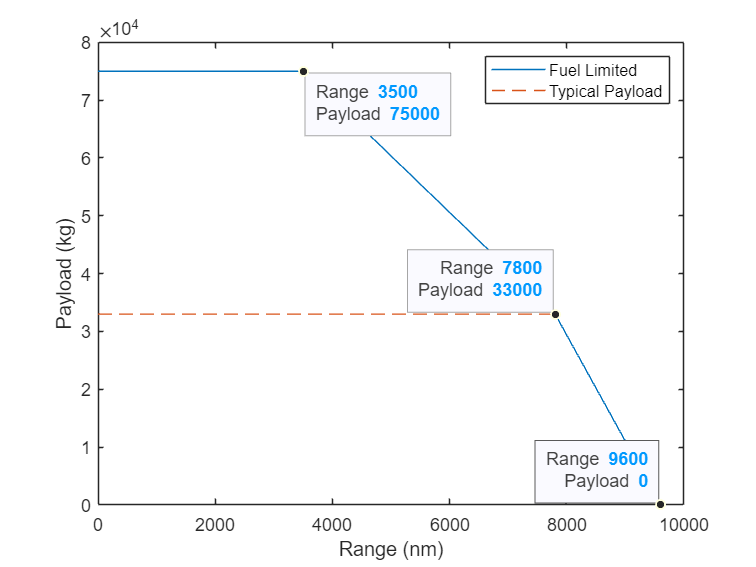

plot([0, Range, Aircraft.Range, FerryRange],[Aircraft.MaxPyld,Aircraft.MaxPyld,Aircraft.DesignPayload,0])
hold on
plot ([0, Range, Aircraft.Range],[Aircraft.DesignPayload,Aircraft.DesignPayload,Aircraft.DesignPayload],'--')
hold off
legend(["Fuel Limited", "Typical Payload"])

xlabel("Range (nm)")
ylabel("Payload (kg)")
ax = gca;
chart = ax.Children(1);
chart.DataTipTemplate.DataTipRows(1).Label="Range";
chart.DataTipTemplate.DataTipRows(2).Label="Payload";
datatip(chart,Aircraft.Range,Aircraft.DesignPayload);
chart2 =ax.Children(2);
chart2.DataTipTemplate.DataTipRows(1).Label="Range";
chart2.DataTipTemplate.DataTipRows(2).Label="Payload";
datatip(chart2,Aircraft.RangemaxPyld,Aircraft.MaxPyld);
ax2 = gca;
chart3 = ax2.Children(2);
datatip(chart3,Aircraft.FerryRange,0);

%
%
%

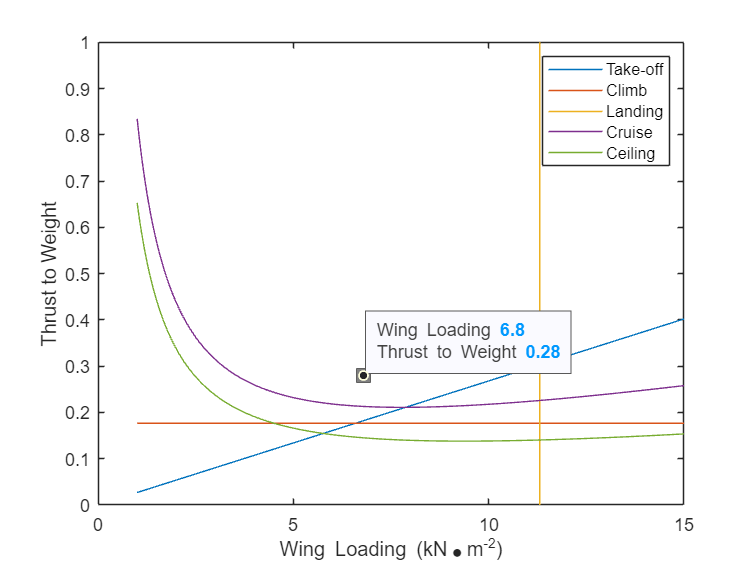

 
[Aircraft,Aircraft.Constraints] = ConstraintsAnalysis(Aircraft,Aircraft.Constraints,MissionTbl);
%
% Initialise arrays
%
% xdata(:,length(Aircraft.Constraints))=0;
% ydata(:,length(Aircraft.Constraints))=0;
% legendData{length(Aircraft.Constraints)};
%
for ii = 1:length(Aircraft.Constraints)
    xdata(:,ii)=Aircraft.Constraints(ii).WS/1000;
    ydata(:,ii)=Aircraft.Constraints(ii).TW;
    legendData{ii}=Aircraft.Constraints(ii).Type;
end
WingLoading=Aircraft.WS;
ThrustoWeight = Aircraft.TW;
designPointX = 9.2    ;
designPointY= 0.25;
plot(xdata,ydata,designPointX,designPointY,'ks','MarkerSize',10,'MarkerFaceColor',[0.5,0.5,0.5])

%hold on
%plot(designPointX,designPointY,'x')
%hold off
xlabel("Wing Loading (kN\bulletm^{-2})");
ylabel("Thrust to Weight");
legend(legendData)

ax3 = gca;
chart4 = ax3.Children(1);
datatip(chart4,designPointX,designPointY);
chart4.DataTipTemplate.DataTipRows(1).Label="Wing Loading";
chart4.DataTipTemplate.DataTipRows(2).Label="Thrust to Weight";